% Importing data
data = readtable("marketing_campaign.csv");
summary(data);

Variables:

    ID: 2240×1 double

        Values:

            Min             0 
            Median     5458.5 
            Max         11191 

    Year_Birth: 2240×1 double

        Values:

            Min         1893  
            Median      1970  
            Max         1996  

    Education: 2240×1 cell array of character vectors

    Marital_Status: 2240×1 cell array of character vectors

    Income: 2240×1 double

        Values:

            Min             1730        
            Median          51382       
            Max             6.6667e+05  
            NumMissing      24          

    Kidhome: 2240×1 double

        Values:

            Min          0    
            Median       0    
            Max          2    

    Teenhome: 2240×1 double

        Values:

            Min          0    
            Median       0    
            Max       

disp([data])

     ID      Year_Birth      Education       Marital_Status      Income      Kidhome    Teenhome     Dt_Customer      Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    AcceptedCmp3    AcceptedCmp4    AcceptedCmp5    AcceptedCmp1    AcceptedCmp2    Complain    Z_CostContact    Z_Revenue    Response
    _____    _____

missingValues = isnan(data.Income);
missingValues

missingValues = 2240×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


%fill missing values with the mean
data.Income = fillmissing(data.Income, 'movmean', size(data.Income, 1));
data.Income

ans = 1.0e+05 *

    0.5814
    0.4634
    0.7161
    0.2665
    0.5829
    0.6251
    0.5564
    0.3345
    0.3035
    0.0565


% Calculate age
data.Age = 2015 - data.Year_Birth;

% Convert Dt_Customer column to datetime
data.Dt_Customer = datetime(data.Dt_Customer, 'InputFormat', 'dd-MM-yyyy');
% Calculate how long they have been a customer
data.Customer_From = years(datetime(2024, 1, 1) - data.Dt_Customer);

% Replace values in the 'Education' column
data.Education = replace(data.Education, {'Graduation', 'PhD', 'Master', '2n Cycle', 'Basic'}, {'Graduate', 'Postgraduate', 'Postgraduate', 'Postgraduate', 'Undergraduate'});

% Replace values in the 'Marital_Status' column and create a new column 'Living_With'
data.Living_With = replace(data.Marital_Status, {'Married', 'Together', 'Single', 'Divorced', 'Widow', 'Absurd', 'YOLO'}, {'Partner', 'Partner', 'Alone', 'Alone', 'Alone', 'Alone', 'Alone'});

% Calculate total number of children and store in a new column 'Total_Children'
data.Total_Children = data.Kidhome + data.Teenhome;

% Parent or not
data.Parent = data.Total_Children > 0;

% Total Spent
data.Total_Spent = sum(data{:, {'MntWines', 'MntFruits', 'MntMeatProducts', ...
    'MntFishProducts', 'MntSweetProducts', 'MntGoldProds'}}, 2);
disp([data]);

     ID      Year_Birth        Education        Marital_Status      Income      Kidhome    Teenhome    Dt_Customer    Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    AcceptedCmp3    AcceptedCmp4    AcceptedCmp5    AcceptedCmp1    AcceptedCmp2    Complain    Z_CostContact    Z_Revenue    Response    Age    Customer

% Assuming 'Dt_Customer' is a datetime array in MATLAB

% Extract day, month, and year components
data.Day = day(data.Dt_Customer);
data.Month = month(data.Dt_Customer);
data.Year = year(data.Dt_Customer);



% Display the resulting DataFrame
disp(data);

     ID      Year_Birth        Education        Marital_Status      Income      Kidhome    Teenhome    Dt_Customer    Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    AcceptedCmp3    AcceptedCmp4    AcceptedCmp5    AcceptedCmp1    AcceptedCmp2    Complain    Z_CostContact    Z_Revenue    Response    Age    Customer

% Assuming 'Dt_Customer' is a datetime array in MATLAB

% Extract day of the week as an integer (1 for Sunday, 2 for Monday, etc.)
dayOfWeekNum = weekday(data.Dt_Customer);

% Map day of the week integer to day names
dayNames = {'Sunday', 'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday'};
dayOfWeekStr = dayNames(dayOfWeekNum)';

% Assign the resulting day of the week strings to the 'Dayofweek' column
data.Dayofweek = dayOfWeekStr;

% Display the resulting DataFrame
disp(data);

     ID      Year_Birth        Education        Marital_Status      Income      Kidhome    Teenhome    Dt_Customer    Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    AcceptedCmp3    AcceptedCmp4    AcceptedCmp5    AcceptedCmp1    AcceptedCmp2    Complain    Z_CostContact    Z_Revenue    Response    Age    Customer

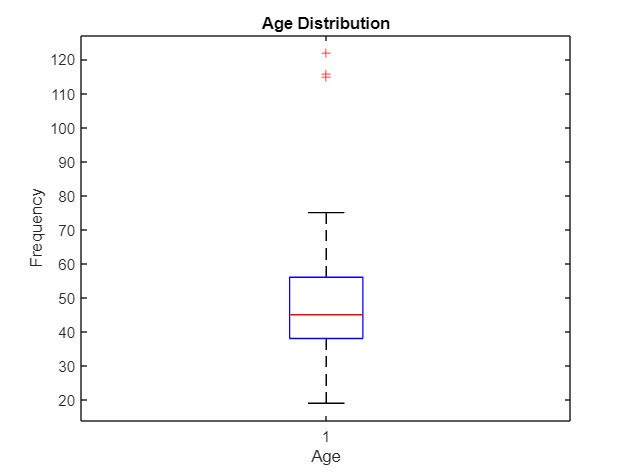

% Visualize age distribution with a histogram
boxplot(data.Age); % Adjust the bin width as needed
xlabel('Age');
ylabel('Frequency');
title('Age Distribution');

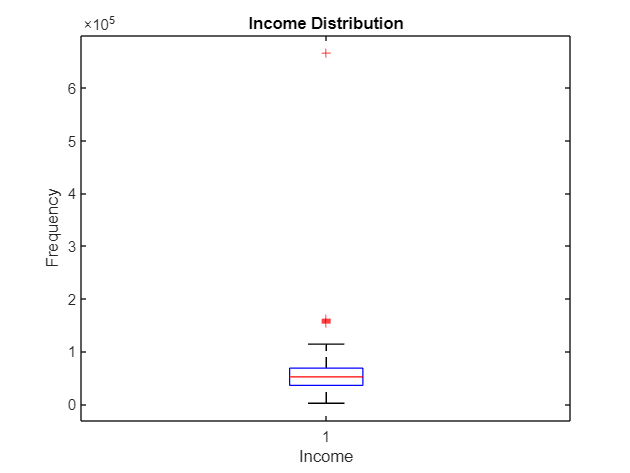

% Visualize income distribution with a histogram
boxplot(data.Income); % Adjust the bin width as needed
xlabel('Income');
ylabel('Frequency');
title('Income Distribution');

% Drop the Outliers
% Filter rows where 'Income' is less than 150000
data = data(data.Income < 150000, :);

% Filter rows where 'Age' is less than 90
data = data(data.Age < 90, :);

disp(data);

     ID      Year_Birth        Education        Marital_Status      Income      Kidhome    Teenhome    Dt_Customer    Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    AcceptedCmp3    AcceptedCmp4    AcceptedCmp5    AcceptedCmp1    AcceptedCmp2    Complain    Z_CostContact    Z_Revenue    Response    Age    Customer

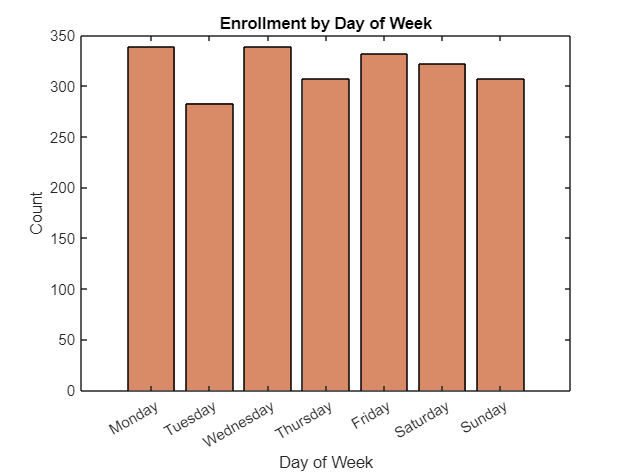

% Plot 1: Day of Week
dayOfWeek = {'Monday', 'Tuesday', 'Wednesday', 'Thursday', 'Friday', 'Saturday', 'Sunday'};
data.Dayofweek = categorical(data.Dayofweek, dayOfWeek);
dayOfWeekCount = countcats(data.Dayofweek);

bar(dayOfWeekCount, 'FaceColor', [0.85, 0.54, 0.4]);
set(gca, 'XTickLabel', dayOfWeek);
title('Enrollment by Day of Week');
ylabel('Count');
xlabel('Day of Week');

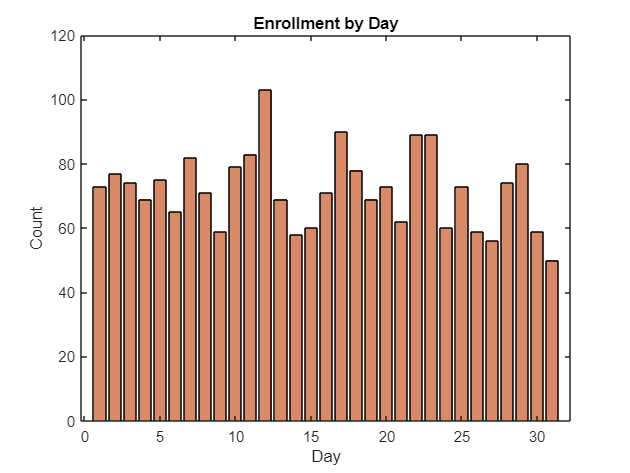


% Plot 2: Day

dayCount = countcats(categorical(data.Day));
bar(dayCount, 'FaceColor', [0.85, 0.54, 0.4]);
title('Enrollment by Day');
ylabel('Count');
xlabel('Day');

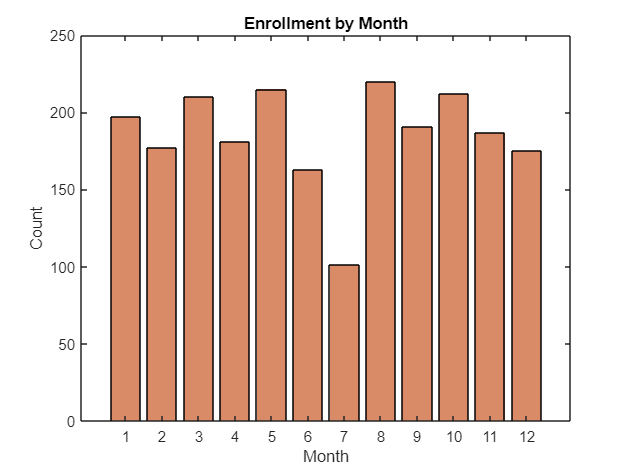


% Plot 3: Month

monthCount = countcats(categorical(data.Month));
bar(monthCount, 'FaceColor', [0.85, 0.54, 0.4]);
title('Enrollment by Month');
ylabel('Count');
xlabel('Month');

% Convert 'Age' column to categorical
group = discretize(data.Age, [10, 20, 30, 40, 50, 60, 70, 80], 'categorical');

% Calculate total spending and average spending for each age group
total_spent = splitapply(@sum, data.Total_Spent, grp2idx(group));
mean_spent = splitapply(@mean, data.Total_Spent, grp2idx(group));

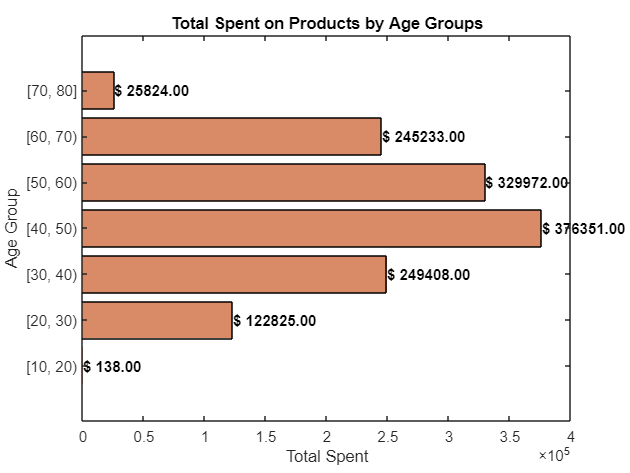


% Plot 1: Total Spent on Products by Age Groups
figure;
barh(total_spent, 'FaceColor', [0.85, 0.54, 0.4]);
yticks(1:numel(categories(group)));
yticklabels(categories(group));
title('Total Spent on Products by Age Groups');
xlabel('Total Spent');
ylabel('Age Group');
hold on ;
% Add annotations to the bars
for i = 1:numel(total_spent)
    text(total_spent(i), i, sprintf('$ %.2f', total_spent(i)), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color', 'black', 'FontWeight', 'bold');
end

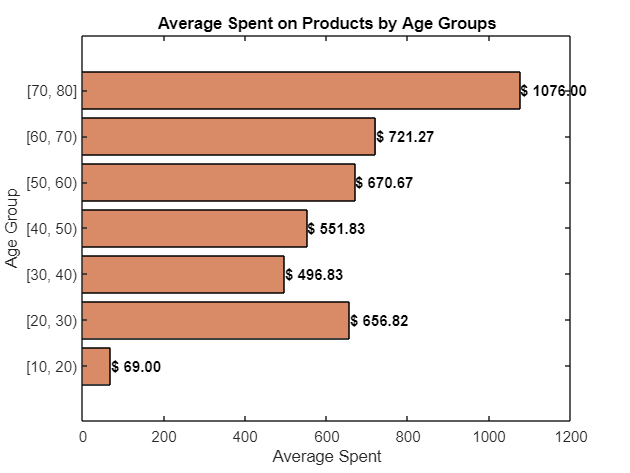

% Plot 2: Average Spent on Products by Age Groups
figure;
barh(mean_spent, 'FaceColor', [0.85, 0.54, 0.4]);
yticks(1:numel(categories(group)));
yticklabels(categories(group));
title('Average Spent on Products by Age Groups');
xlabel('Average Spent');
ylabel('Age Group');

% Add annotations to the bars
for i = 1:numel(mean_spent)
    text(mean_spent(i), i, sprintf('$ %.2f', mean_spent(i)), 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'Color', 'black', 'FontWeight', 'bold');
end

scaled_data  = data;
%%% Remove Unnecessary Columns
% Specify the names of the columns to be dropped
columns_to_drop = {'ID', 'Year_Birth', 'Marital_Status', 'Dt_Customer', 'Z_CostContact', 'Z_Revenue','Dayofweek','Living_With','AcceptedCmp1','AcceptedCmp2','AcceptedCmp3','AcceptedCmp4','AcceptedCmp5','Day','Month','Year'};

% Remove the specified columns from the table
scaled_data(:, columns_to_drop) = [];


scaled_data

scaled_data = 2229×23 table
        Education        Income    Kidhome    Teenhome    Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    Complain    Response    Age    Customer_From    Total_Children    Parent    Total_Spent
    _________________    ______    _______    ________    _______    ________    _________    

% Dealing with Categorical Variables

% Define the mapping dictionary
mappingDict = containers.Map({'Undergraduate', 'Graduate', 'Postgraduate'}, {0, 1, 2});

% Map values in the 'Education' column using the mapping dictionary
scaled_data.Education = cellfun(@(x) mappingDict(x), scaled_data.Education);

disp([scaled_data])

    Education      Income      Kidhome    Teenhome    Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    Complain    Response    Age    Customer_From    Total_Children    Parent    Total_Spent
    _________    __________    _______    ________    _______    ________    _________    _______________    

% Assuming scaled_data is a table

% Logical indexing to replace false with 0 and true with 1
scaled_data.Parent = double(scaled_data.Parent); % Convert logical to double
scaled_data.Parent(scaled_data.Parent == false) = 0; % Replace false with 0
scaled_data.Parent(scaled_data.Parent == true) = 1;  % Replace true with 1
disp(head(scaled_data))

    Education    Income    Kidhome    Teenhome    Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    Complain    Response    Age    Customer_From    Total_Children    Parent    Total_Spent
    _________    ______    _______    ________    _______    ________    _________    _______________    _______

% Standardize the numeric data
numeric_data = scaled_data{:, :}; % Extract numeric data from the table
scaled_numeric_data = zscore(numeric_data); % Standardize the numeric data

% Create a new table with the standardized numeric data
final_scaled = array2table(scaled_numeric_data, 'VariableNames', scaled_data.Properties.VariableNames);

% Display the first few rows of the scaled data
disp(head(final_scaled));

    Education     Income     Kidhome     Teenhome    Recency     MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    Complain    Response      Age       Customer_From    Total_Children    Parent     Total_Spent
    _________    ________    ________    ________    ________    ________    _________    _______________    <

rng(1)
clustering_data = final_scaled

clustering_data = 2229×23 table
    Education     Income     Kidhome     Teenhome    Recency     MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    Complain    Response      Age       Customer_From    Total_Children    Parent     Total_Spent
    _________    ________    ________    ________    ________    ________    _________    

final_scaled = table2array(final_scaled);
% Set number of clusters to 5
numClusters = 5;

opts = statset("Display","final");
% Perform K-means clustering
[idx, C] = kmeans(final_scaled, numClusters , "Replicates",10 , "Options",opts);

Replicate 1, 34 iterations, total sum of distances = 30089.3.
Replicate 2, 17 iterations, total sum of distances = 29194.6.
Replicate 3, 30 iterations, total sum of distances = 29508.8.
Replicate 4, 9 iterations, total sum of distances = 29508.7.
Replicate 5, 13 iterations, total sum of distances = 29653.
Replicate 6, 23 iterations, total sum of distances = 29033.5.
Replicate 7, 43 iterations, total sum of distances = 30089.1.
Replicate 8, 11 iterations, total sum of distances = 29763.3.
Replicate 9, 15 iterations, total sum of distances = 29509.1.
Replicate 10, 23 iterations, total sum of distances = 30313.1.
Best total sum of distances = 29033.5


[idx , C] = kmeans(final_scaled,numClusters,"Replicates",6);
% Assign cluster labels to the original data
scaled_data.Cluster = idx;

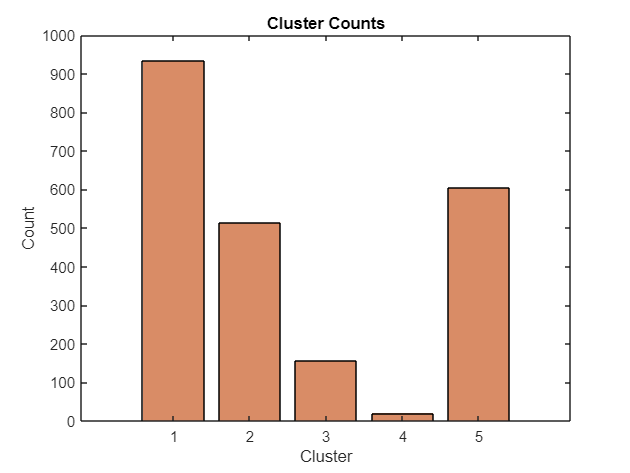

rng(1)
% Visualize cluster counts using a bar plot
figure;
clusterCounts = histcounts(idx, 1:numClusters+1);
bar(1:numClusters, clusterCounts, 'FaceColor', [0.85 0.55 0.4]); % Adjust color as needed
xlabel('Cluster');
ylabel('Count');
title('Cluster Counts');

figure;
disp(final_scaled)

   -0.8224    0.3160   -0.8254   -0.9315    0.3072    0.9799    1.5504    1.7358    2.4562    1.4717    0.8425    0.3589    1.4052    2.6334   -0.5590    0.6898   -0.0951    2.3814    1.0155    1.5289   -1.2660   -1.5875    1.6829
   -0.8224   -0.2565    1.0311    0.9043   -0.3837   -0.8730   -0.6375   -0.7262   -0.6516   -0.6329   -0.7317   -0.1688   -1.1169   -0.5853   -1.1759   -0.1384   -0.0951   -0.4197    1.2717   -1.1905    1.3937    0.6296   -0.9626
   -0.8224    0.9701   -0.8254   -0.9315   -0.7982    0.3593    0.5696   -0.1745    1.3411   -0.1490   -0.0406   -0.6964    1.4052   -0.2277    1.2916   -0.5525   -0.0951   -0.4197    0.3322   -0.2066   -1.2660   -1.5875    0.2836
   -0.8224   -1.2127    1.0311   -0.9315   -0.7982   -0.8730   -0.5620   -0.6624   -0.5053   -0.5845   -0.7509   -0.1688   -0.7566   -0.9429   -0.5590    0.2757   -0.0951   -0.4197   -1.2907   -1.0619    0.0638    0.6296   -0.9193
    1.0162    0.3235    1.0311   -0.9315    1.5509   -0.3919    0.4188   -0.

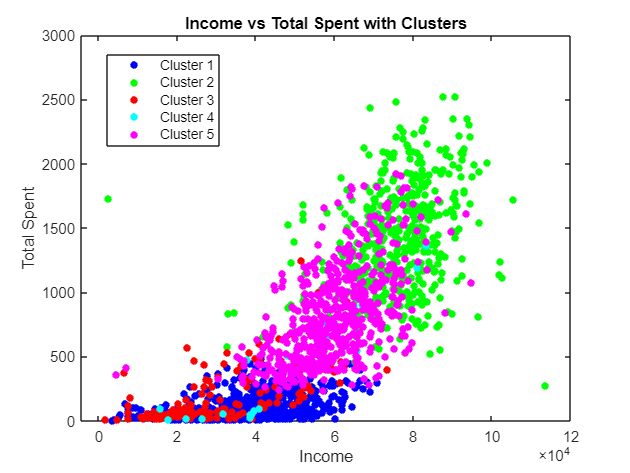

colors = [0.85 0.55 0.4;   % Cluster 1 color
          0.93 0.68 0.52;  % Cluster 2 color
          0.73 0.45 0.3;   % Cluster 3 color
          0.85 0.7 0.55;   % Cluster 4 color
          0.62 0.35 0.2];  % Cluster 5 color

gscatter(scaled_data.Income , scaled_data.Total_Spent,scaled_data.Cluster,"bgrcm",'.',15); % Adjust marker size as needed
xlabel('Income');
ylabel('Total Spent');
title('Income vs Total Spent with Clusters');
legend('Cluster 1', 'Cluster 2', 'Cluster 3', 'Cluster 4', 'Cluster 5');

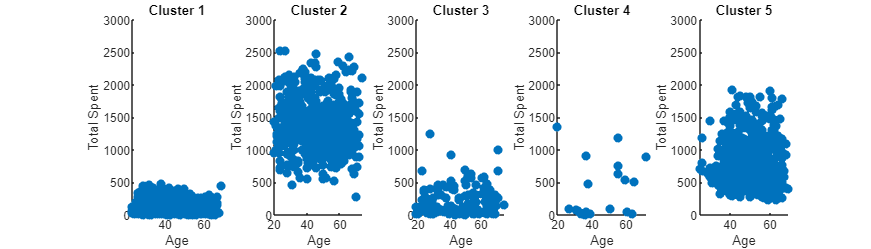

% Create scatter plots for each cluster
figure('Position', [90, 90, 1400, 400]);
for i = 1:max(scaled_data.Cluster)
    subplot(1, max(scaled_data.Cluster), i);
    idx = scaled_data.Cluster == i;
    scatter(scaled_data.Age(idx), scaled_data.Total_Spent(idx), 'filled');
    xlabel('Age');
    ylim([0,3000])
    ylabel('Total Spent');
    title(['Cluster ' num2str(i)]);
end

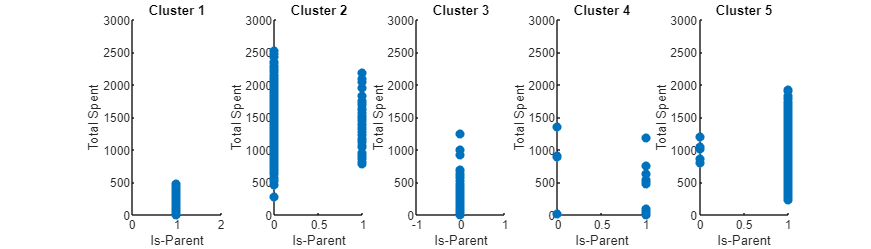

% Create scatter plots for each cluster
figure('Position', [90, 90, 1400, 400]);
for i = 1:max(scaled_data.Cluster)
    subplot(1, max(scaled_data.Cluster), i);
    idx = scaled_data.Cluster == i;
    scatter(scaled_data.Parent(idx), scaled_data.Total_Spent(idx), 'filled');
    xlabel('Is-Parent');
    ylim([0 ,3000])
    ylabel('Total Spent');
    title(['Cluster ' num2str(i)]);
end

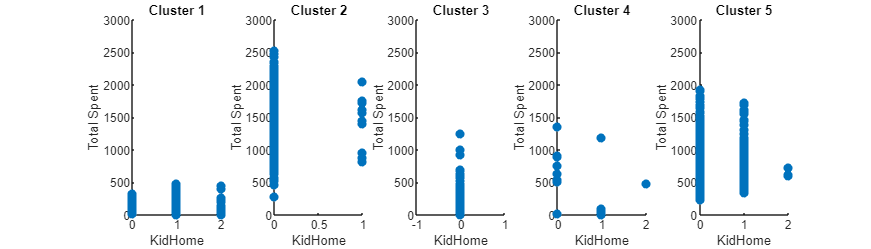

% Create scatter plots for each cluster
figure('Position', [90, 90, 1400, 400]);
for i = 1:max(scaled_data.Cluster)
    subplot(1, max(scaled_data.Cluster), i);
    idx = scaled_data.Cluster == i;
    scatter(scaled_data.Kidhome(idx), scaled_data.Total_Spent(idx), 'filled');
    xlabel('KidHome');
    ylim([0,3000])
    ylabel('Total Spent');
    title(['Cluster ' num2str(i)]);
end

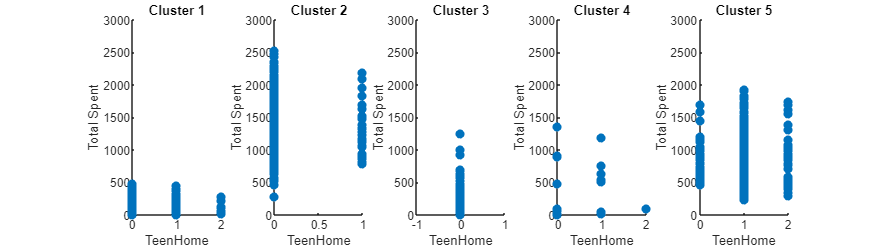

% Create scatter plots for each cluster
figure('Position', [90, 90, 1400, 400]);
for i = 1:max(scaled_data.Cluster)
    subplot(1, max(scaled_data.Cluster), i);
    idx = scaled_data.Cluster == i;
    scatter(scaled_data.Teenhome(idx), scaled_data.Total_Spent(idx), 'filled');
    xlabel('TeenHome');
    ylim([0,3000])
    ylabel('Total Spent');
    title(['Cluster ' num2str(i)]);
end

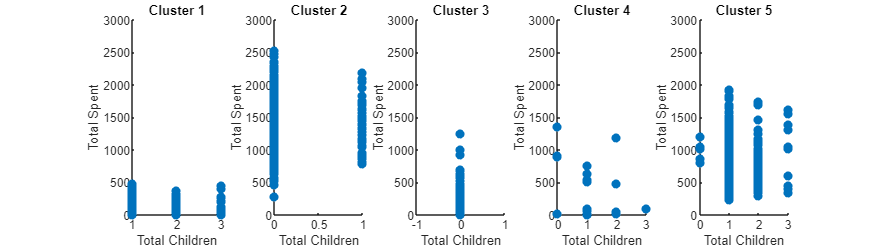

% Create scatter plots for each cluster
figure('Position', [90, 90, 1400, 400]);
for i = 1:max(scaled_data.Cluster)
    subplot(1, max(scaled_data.Cluster), i);
    idx = scaled_data.Cluster == i;
    scatter(scaled_data.Total_Children(idx), scaled_data.Total_Spent(idx), 'filled');
    xlabel('Total Children');
    ylim([0,3000])
    ylabel('Total Spent');
    title(['Cluster ' num2str(i)]);
end

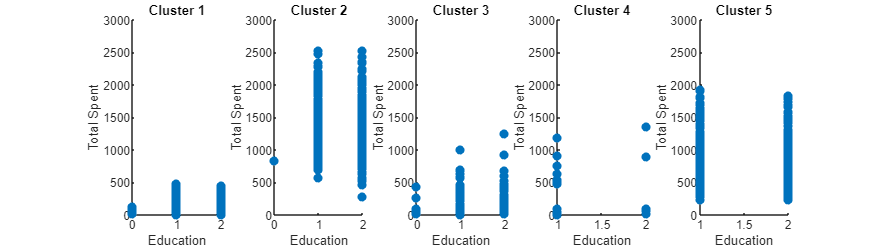

% Create scatter plots for each cluster
figure('Position', [90, 90, 1400, 400]);
for i = 1:max(scaled_data.Cluster)
    subplot(1, max(scaled_data.Cluster), i);
    idx = scaled_data.Cluster == i;
    scatter(scaled_data.Education(idx), scaled_data.Total_Spent(idx), 'filled');
    xlabel('Education');
    ylim([0,3000])
    ylabel('Total Spent');
    title(['Cluster ' num2str(i)]);
end


%{
cluster 1: age between 20 and 70
            parents
cluster 2 span all ages
            not parents
cluster 3 span all ages
            not parents
cluster 4 span all ages
            parents
cluster 5 age between 25 and 70
            parents
%}


rng(1); % Set a random seed for reproducibility
X=scaled_data(:, 1:end-1);
Y=scaled_data.Cluster;
totalSamples = size(X, 1);

% Proportions for splitting: 70% training, 20% validation, 10% testing
[trainInd, valInd, testInd] = dividerand(totalSamples, 0.7, 0.2, 0.1);

% Split data into training, validation, and testing sets
trainData = X(trainInd, :);
trainLabels = Y(trainInd);

validationData = X(valInd, :);
validationLabels = Y(valInd);

testData = X(testInd, :);
testLabels = Y(testInd);

% Display sizes
disp(['Training samples: ', num2str(length(trainInd))])

Training samples: 1560


disp(['Validation samples: ', num2str(length(valInd))])

Validation samples: 446


disp(['Testing samples: ', num2str(length(testInd))])

Testing samples: 223


%knn model for k=3
Mdl = fitcknn(trainData,trainLabels,'NumNeighbors',3,'Standardize',1);

predictedLabels=predict(Mdl,testData);
% Calculate accuracy
accuracy = sum(predictedLabels == testLabels) / numel(testLabels) * 100;
disp(['Accuracy on test set: ', num2str(accuracy), '%']);

Accuracy on test set: 95.5157%


truePositives = sum((predictedLabels == 1) & (testLabels == 1));
predictedPositives = sum(predictedLabels == 1);
actualPositives = sum(testLabels == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);
fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 95.56%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 97.73%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 96.63%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(testLabels, predictedLabels);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 213 out of 232 were correctly predicted

    86     0     0     0     2
     0    59     1     0     3
     0     0     8     0     0
     0     0     0     1     0
     4     0     0     0    59





%knn model for k=5
Modl = fitcknn(trainData,trainLabels,'NumNeighbors',5,'Standardize',1);
prediictedLabels=predict(Modl,testData);
% Calculate accuracy
accuracy = sum(prediictedLabels == testLabels) / numel(testLabels) * 100;
disp(['Accuracy on test set: ', num2str(accuracy), '%']);

Accuracy on test set: 94.6188%


truePositives = sum((prediictedLabels == 1) & (testLabels == 1));
predictedPositives = sum(prediictedLabels == 1);
actualPositives = sum(testLabels == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 94.51%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 97.73%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 96.09%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(testLabels, prediictedLabels);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 211 out of 223 were correctly predicted

    86     0     0     0     2
     0    58     0     0     5
     0     0     8     0     0
     0     0     0     1     0
     5     0     0     0    58




%knn model for k=7
Mdel = fitcknn(trainData,trainLabels,'NumNeighbors',7,'Standardize',1);
predicteddLabels=predict(Mdel,testData);
% Calculate accuracy
accuracy = sum(predicteddLabels == testLabels) / numel(testLabels) * 100;
disp(['Accuracy on test set: ', num2str(accuracy), '%']);

Accuracy on test set: 95.9641%


truePositives = sum((predicteddLabels == 1) & (testLabels == 1));
predictedPositives = sum(predicteddLabels == 1);
actualPositives = sum(testLabels == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 96.67%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 98.86%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 97.75%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(testLabels, predicteddLabels);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 214 out of 223 were correctly predicted

    87     0     0     0     1
     0    58     0     0     5
     0     0     8     0     0
     0     0     0     1     0
     3     0     0     0    60




%knn model for k=9
Mdle = fitcknn(trainData,trainLabels,'NumNeighbors',9,'Standardize',1);


predictedLabelss=predict(Mdle,testData);
% Calculate accuracy
accuracy = sum(predictedLabelss == testLabels) / numel(testLabels) * 100;
disp(['Accuracy on test set: ', num2str(accuracy), '%']);

Accuracy on test set: 95.5157%


truePositives = sum((predictedLabelss == 1) & (testLabels == 1));
predictedPositives = sum(predictedLabelss == 1);
actualPositives = sum(testLabels == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 95.60%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 98.86%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 97.21%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(testLabels, predictedLabelss);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 213 out of 224 were correctly predicted

    87     0     0     0     1
     0    58     0     0     5
     0     0     8     0     0
     0     0     0     1     0
     4     0     0     0    59




%decision tree model
treeModel = fitctree(trainData,trainLabels); 
predictedLabels1=predict(treeModel, testData);

accuracy = sum(predictedLabels1 == testLabels) / numel(testLabels) * 100;
disp(['Accuracy on test set: ', num2str(accuracy), '%']);

Accuracy on test set: 95.0673%


truePositives = sum((predictedLabels1 == 1) & (testLabels == 1));
predictedPositives = sum(predictedLabels1 == 1);
actualPositives = sum(testLabels == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 95.60%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 98.86%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 97.21%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(testLabels, predictedLabels1);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 212 out of 223 were correctly predicted

    87     0     0     0     1
     0    61     0     0     2
     0     0     8     0     0
     0     0     0     0     1
     4     3     0     0    56




%svm model
SVMModel = fitcecoc(trainData, trainLabels);

predictedLabels2=predict(SVMModel, testData);
accuracy = sum(predictedLabels2 == testLabels) / numel(testLabels) * 100;
disp(['Accuracy on test set: ', num2str(accuracy), '%']);

Accuracy on test set: 12.5561%


truePositives = sum((predictedLabels2 == 1) & (testLabels == 1));
predictedPositives = sum(predictedLabels2 == 1);
actualPositives = sum(testLabels == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 12.96%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 15.91%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 14.29%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(testLabels, predictedLabels2);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 28 out of 207 were correctly predicted

    14     0     0     0    74
    45     2     0    16     0
     1     0     0     0     7
     0     0     0     0     1
    48     2     0     1    12



%svm model

% Z-Score Normalization (Standardization)
meanVals = mean(trainData);
stdVals = std(trainData);
trainData = (trainData - meanVals) ./ stdVals;
validationData = (validationData - meanVals) ./ stdVals;
testData = (testData - meanVals) ./ stdVals;

% SVM model
SVMModel = fitcecoc(trainData, trainLabels);

predictedLabels = predict(SVMModel, testData);
accuracy = sum(predictedLabels == testLabels) / numel(testLabels) * 100;
disp(['Accuracy on test set: ', num2str(accuracy), '%']);

Accuracy on test set: 98.2063%



truePositives = sum((predictedLabels == 1) & (testLabels == 1));
predictedPositives = sum(predictedLabels == 1);
actualPositives = sum(testLabels == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 100.00%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 97.73%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 98.85%




% Assuming y_true and y_pred are available
confusionMat = confusionmat(testLabels, predictedLabels);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 219  out of 223 were correctly predicted

    86     0     0     0     2
     0    62     0     0     1
     0     0     8     0     0
     0     0     0     1     0
     0     1     0     0    62



    
%cvpartition
rng(1); % Set a random seed for reproducibility
c = cvpartition(Y, 'HoldOut', 0.4);
XTrain = X(training(c), :);

% Extract training labels
YTrain = Y(training(c));

% Extract temporary testing data
XTestTemp = X(test(c), :);

% Extract temporary testing labels
YTestTemp = Y(test(c));

% Further split the temporary test set into validation and test sets
c2 = cvpartition(length(YTestTemp), 'HoldOut', 0.5);

XVal = XTestTemp(test(c2), :);
YVal = YTestTemp(test(c2));
XTest = XTestTemp(training(c2), :);
YTest = YTestTemp(training(c2));

%decison tree model
treeModel1 = fitctree(XTrain,YTrain); 
X1Predicted=predict(treeModel1, XTest);

accuracy = sum(X1Predicted == YTest) / numel(YTest) * 100

accuracy = 95.5157

disp(['Accuracy: ', num2str(accuracy)])

Accuracy: 95.5157


truePositives = sum((X1Predicted == 1) & (YTest == 1));
predictedPositives = sum(X1Predicted == 1);
actualPositives = sum(YTest == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 99.47%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 97.93%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 98.69%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(YTest, X1Predicted);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) 

   189     0     0     0     4
     0    85     0     0     7
     0     1    28     0     1
     0     0     0     1     2
     1     4     0     0   123



%svm model
SVMModel1 = fitcecoc(XTrain,YTrain);
X2Predicted=predict(SVMModel1, XTest);
accuracy = sum(X2Predicted == YTest) / numel(YTest) * 100;
disp(['Accuracy: ', num2str(accuracy)])

Accuracy: 8.296


truePositives = sum((X2Predicted == 1) & (YTest == 1));
predictedPositives = sum(X2Predicted == 1);
actualPositives = sum(YTest == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 33.33%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 4.15%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 7.37%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(YTest, X2Predicted);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat)% 37 out of 446 were correctly predicted

     8     3     0    14   168
     0     2     5    84     1
     0     9     1     2    18
     0     0     0     2     1
    16     3    17    68    24



%svm model 2
rng(1); % Set a random seed for reproducibility

% Z-Score Normalization (Standardization)
meanVals = mean(X);
stdVals = std(X);
X = (X - meanVals) ./ stdVals;

% Partition data into training and temporary testing sets
c = cvpartition(Y, 'HoldOut', 0.4);
XTrain = X(training(c), :);
YTrain = Y(training(c));
XTestTemp = X(test(c), :);
YTestTemp = Y(test(c));

% Further split the temporary test set into validation and test sets
c2 = cvpartition(length(YTestTemp), 'HoldOut', 0.5);
XVal = XTestTemp(test(c2), :);
YVal = YTestTemp(test(c2));
XTest = XTestTemp(training(c2), :);
YTest = YTestTemp(training(c2));

% Train SVM model
SVMModel1 = fitcecoc(XTrain,YTrain);

% Predict on validation set
X2Predicted = predict(SVMModel1, XVal);
accuracy = sum(X2Predicted == YVal) / numel(YVal) * 100;
disp(['Accuracy on validation set: ', num2str(accuracy)])

Accuracy on validation set: 97.5281



% Predict on test set
X2Predicted = predict(SVMModel1, XTest);
accuracy = sum(X2Predicted == YTest) / numel(YTest) * 100;
disp(['Accuracy on test set: ', num2str(accuracy)])

Accuracy on test set: 98.6547



truePositives = sum((X2Predicted == 1) & (YTest == 1));
predictedPositives = sum(X2Predicted == 1);
actualPositives = sum(YTest == 1);

precision = truePositives / predictedPositives;


recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 100.00%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 98.45%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 99.22%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(YTest, X2Predicted);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat)% 440 out of 446 were correctly predicted

   190     0     0     0     3
     0    91     0     0     1
     0     1    29     0     0
     0     0     0     3     0
     0     1     0     0   127



%knn model for k=3
Mdl1 = fitcknn(XTrain,YTrain,'NumNeighbors',3,'Standardize',1);

X3Predicted=predict(Mdl1,XTest);
accuracy = sum(X3Predicted == YTest) / numel(YTest) * 100;
disp(['Accuracy: ', num2str(accuracy)])

Accuracy: 95.9641


truePositives = sum((X3Predicted == 1) & (YTest == 1));
predictedPositives = sum(X3Predicted == 1);
actualPositives = sum(YTest == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 96.46%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 98.96%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 97.70%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(YTest, X3Predicted);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 428 out of 446 were correctly predicted

   191     0     0     0     2
     0    86     1     0     5
     0     2    28     0     0
     0     0     0     3     0
     7     1     0     0   120



%knn model for k=5
Mdl2 = fitcknn(XTrain,YTrain,'NumNeighbors',5,'Standardize',1);

X3Predicted=predict(Mdl2,XTest);
accuracy = sum(X3Predicted == YTest) / numel(YTest) * 100;
disp(['Accuracy: ', num2str(accuracy)])

Accuracy: 95.7399


truePositives = sum((X3Predicted == 1) & (YTest == 1));
predictedPositives = sum(X3Predicted == 1);
actualPositives = sum(YTest == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 95.50%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 98.96%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 97.20%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(YTest, X3Predicted);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 427 out of 446 were correctly predicted

   191     0     0     0     2
     0    88     0     0     4
     0     2    28     0     0
     0     0     0     3     0
     9     2     0     0   117



%knn model for k=7
Mdl3 = fitcknn(XTrain,YTrain,'NumNeighbors',7,'Standardize',1);

X3Predicted=predict(Mdl3,XTest);
accuracy = sum(X3Predicted == YTest) / numel(YTest) * 100;
disp(['Accuracy: ', num2str(accuracy)])

Accuracy: 95.9641


truePositives = sum((X3Predicted == 1) & (YTest == 1));
predictedPositives = sum(X3Predicted == 1);
actualPositives = sum(YTest == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 95.02%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 98.96%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 96.95%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(YTest, X3Predicted);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 428 out of 446 were correctly predicted

   191     0     0     0     2
     0    88     0     0     4
     0     1    29     0     0
     0     0     0     3     0
    10     1     0     0   117



%knn model for k=9
Mdl4 = fitcknn(XTrain,YTrain,'NumNeighbors',9,'Standardize',1);

X3Predicted=predict(Mdl4,XTest);
accuracy = sum(X3Predicted == YTest) / numel(YTest) * 100;
disp(['Accuracy: ', num2str(accuracy)])

Accuracy: 95.9641


truePositives = sum((X3Predicted == 1) & (YTest == 1));
predictedPositives = sum(X3Predicted == 1);
actualPositives = sum(YTest == 1);

precision = truePositives / predictedPositives;
recall = truePositives / actualPositives;


f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 95.50%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 98.96%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 97.20%


% Assuming y_true and y_pred are available
confusionMat = confusionmat(YTest, X3Predicted);

% Extracting true positives, false positives, false negatives, true negatives
TP = confusionMat(1,1);
FP = confusionMat(1,2);
FN = confusionMat(2,1);
TN = confusionMat(2,2);

% Display the confusion matrix
disp(confusionMat) % 428 out of 446 were correctly predicted

   191     0     0     0     2
     0    88     0     0     4
     0     3    27     0     0
     0     0     0     3     0
     9     0     0     0   119



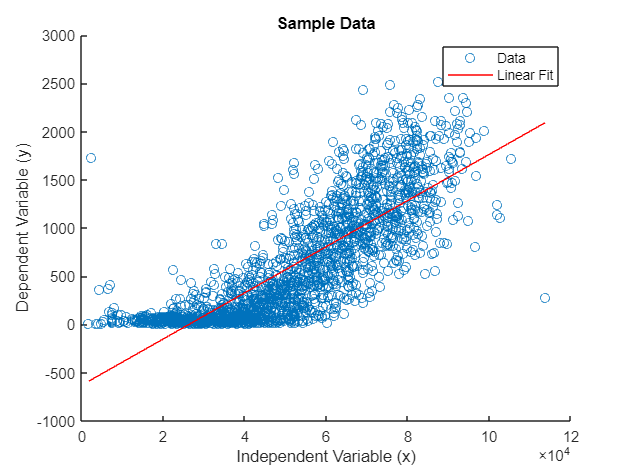

% Linear Regression
x = scaled_data.Income;
y = scaled_data.Total_Spent;

% Plotting the data
figure;
scatter(x, y); 
xlabel('Independent Variable (x)');
ylabel('Dependent Variable (y)');
title('Sample Data');

% Linear regression
lm = fitlm(x,y);
y_pred = predict(lm, x);

% Plotting the linear fit
hold on;
plot(x, y_pred, '-r');
legend('Data', 'Linear Fit');
hold off;


% Display linear regression results
disp(lm);

Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue   
                   ________    __________    _______    ___________

    (Intercept)     -629.73        19.663    -32.026    1.9425e-185
    x1             0.023926    0.00035375     67.636              0


Number of observations: 2229, Error degrees of freedom: 2227
Root Mean Squared Error: 344
R-squared: 0.673,  Adjusted R-Squared: 0.672
F-statistic vs. constant model: 4.57e+03, p-value = 0


R_squared = lm.Rsquared.Ordinary;
disp(['Coefficient of Determination (R^2) for linear regression: ', num2str(R_squared)]);

Coefficient of Determination (R^2) for linear regression: 0.67258


RMSE = sqrt(mean((y - y_pred).^2));
disp(['Root Mean Squared Error (RMSE) for linear regression: ', num2str(RMSE)]);

Root Mean Squared Error (RMSE) for linear regression: 343.8378


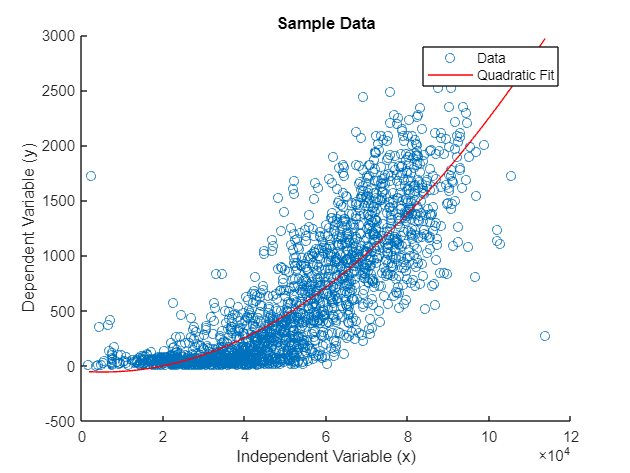


% Quadratic Regression
x1 = scaled_data.Income;
y1 = scaled_data.Total_Spent;

% Plotting the data
figure; % Open a new figure window for the quadratic plot
scatter(x1, y1); 
xlabel('Independent Variable (x)');
ylabel('Dependent Variable (y)');
title('Sample Data');

% Fitting a quadratic (2nd degree) polynomial
p = polyfit(x1, y1, 2);  % p contains the coefficients

% Generating values for the polynomial
x1_fit = linspace(min(x1), max(x1), 100); % Generating 100 points for a smooth curve
y1_fit = polyval(p, x1_fit);

% Plotting the quadratic fit
hold on;
plot(x1_fit, y1_fit, '-r');
legend('Data', 'Quadratic Fit');
hold off;


% Display quadratic regression results
disp('Quadratic Regression Coefficients:');

Quadratic Regression Coefficients:


disp(p);

    0.0000   -0.0027  -50.7452



R_squared_quad = 1 - sum((y1 - polyval(p, x1)).^2) / sum((y1 - mean(y1)).^2);
disp(['Coefficient of Determination (R^2) for quadratic regression: ', num2str(R_squared_quad)]);

Coefficient of Determination (R^2) for quadratic regression: 0.7112



% Assume newIncome is the income value for which you want to predict the total spent
newIncome = 65400; % Example value

% Predict total spent for the new income value using linear regression
predictedTotalSpent_linear = predict(lm, newIncome);
disp(['Predicted total spent for an income of ', num2str(newIncome), ' (Linear): ', num2str(predictedTotalSpent_linear)]);

Predicted total spent for an income of 65400 (Linear): 935.0484



% Predict total spent for the new income value using quadratic regression
predictedTotalSpent_poly = polyval(p, newIncome);
disp(['Predicted total spent for an income of ', num2str(newIncome), ' (Quadratic): ', num2str(predictedTotalSpent_poly)]);

Predicted total spent for an income of 65400 (Quadratic): 873.908
